%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% demo_graphical_learning_label_propagation.m
%
% 75-minute graphical learning recitation, Example 3:
% Semi-supervised learning by label propagation / harmonic extension.
%
% Message to students:
%   Griffin's notes give us the graph Laplacian and the spectral viewpoint.
%   With only one extra idea -- "labels should vary smoothly on the graph" --
%   we can predict unknown node labels from a few known ones.
%
% Real-world interpretation:
%   - predict political preference from a few labeled accounts in a social network
%   - predict fraud risk from a few flagged accounts
%   - predict infected / noninfected nodes from partial observations
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

clear; close all; clc;


%% ------------------------------------------------------------------------
% STEP 1. Build a graph with two communities
% -------------------------------------------------------------------------
% We reuse the same kind of graph as in the spectral clustering example.

n1 = 8; n2 = 8;
A1 = ones(n1) - eye(n1);
A2 = ones(n2) - eye(n2);
A = blkdiag(A1,A2);
bridge_edges = [4,10; 5,11; 7,13];
for k = 1:size(bridge_edges,1)
    i = bridge_edges(k,1); j = bridge_edges(k,2);
    A(i,j)=1; A(j,i)=1;
end
G = graph(A);
n = numnodes(G);


%% ------------------------------------------------------------------------
% STEP 2. Define a small set of labeled nodes
% -------------------------------------------------------------------------
% Suppose label +1 = "Group A" and label -1 = "Group B".
% We reveal only 2 labeled nodes in each community.

Labeled = [1,3, 12,15];
yL = [1;1;-1;-1];
Unlabeled = setdiff(1:n, Labeled);


%% ------------------------------------------------------------------------
% STEP 3. Graph Laplacian and harmonic extension
% -------------------------------------------------------------------------
D = diag(sum(A,2));
L = D - A;

% Partition L according to labeled/unlabeled sets:
% [ L_UU  L_UL ] [f_U] = [0]
% [ L_LU  L_LL ] [f_L]   [*]
%
% The harmonic extension condition for unlabeled nodes is:
%   L_UU f_U = - L_UL f_L
%
% This is exactly the discrete analogue of a harmonic function.

L_UU = L(Unlabeled, Unlabeled);
L_UL = L(Unlabeled, Labeled);

fU = -L_UU \ (L_UL * yL);

% Combine full score vector
f = zeros(n,1);
f(Labeled) = yL;
f(Unlabeled) = fU;

% Turn smooth score into hard label by sign
pred = sign(f);
pred(pred==0) = 1;   % tie-break convention


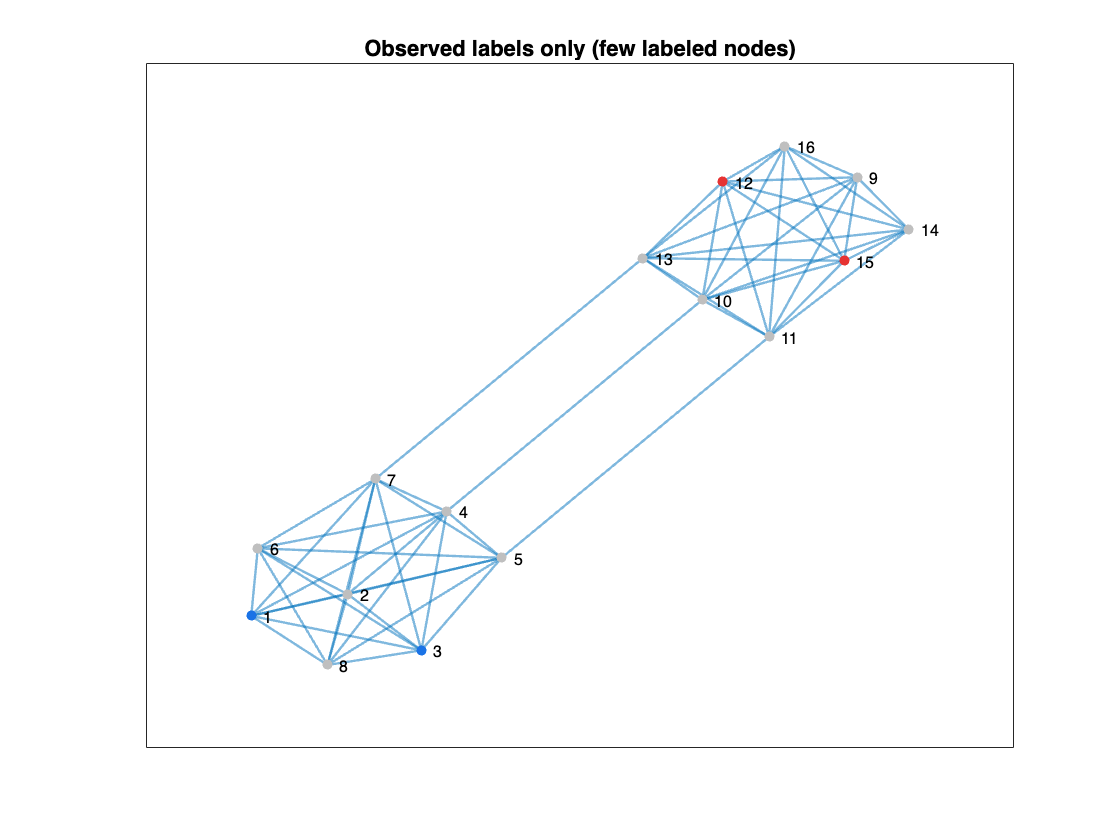

%% ------------------------------------------------------------------------
% STEP 4. Visualize known labels and predicted labels
% -------------------------------------------------------------------------
figure('Color','w','Name','Label propagation: observed labels');
p1 = plot(G,'Layout','force','LineWidth',1.2);
title('Observed labels only (few labeled nodes)');

% start all gray
highlight(p1,1:n,'NodeColor',[0.75 0.75 0.75]);
% positive labeled nodes blue, negative labeled nodes red
highlight(p1, Labeled(yL>0), 'NodeColor', [0.1 0.45 0.9]);
highlight(p1, Labeled(yL<0), 'NodeColor', [0.9 0.2 0.2]);

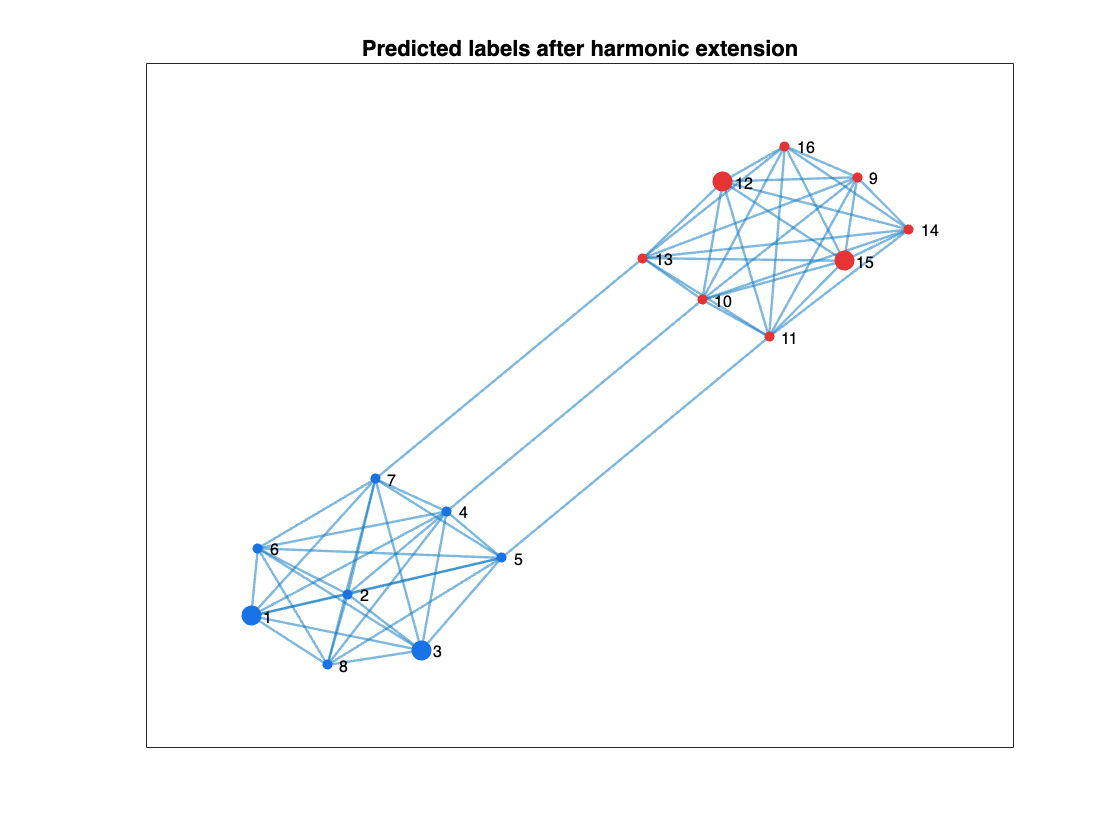


figure('Color','w','Name','Label propagation: predicted labels');
p2 = plot(G,'Layout','force','LineWidth',1.2);
title('Predicted labels after harmonic extension');

% Color all nodes according to predicted sign
highlight(p2, find(pred>0), 'NodeColor', [0.1 0.45 0.9]);
highlight(p2, find(pred<0), 'NodeColor', [0.9 0.2 0.2]);
% Make originally labeled nodes larger
highlight(p2, Labeled, 'MarkerSize', 9);

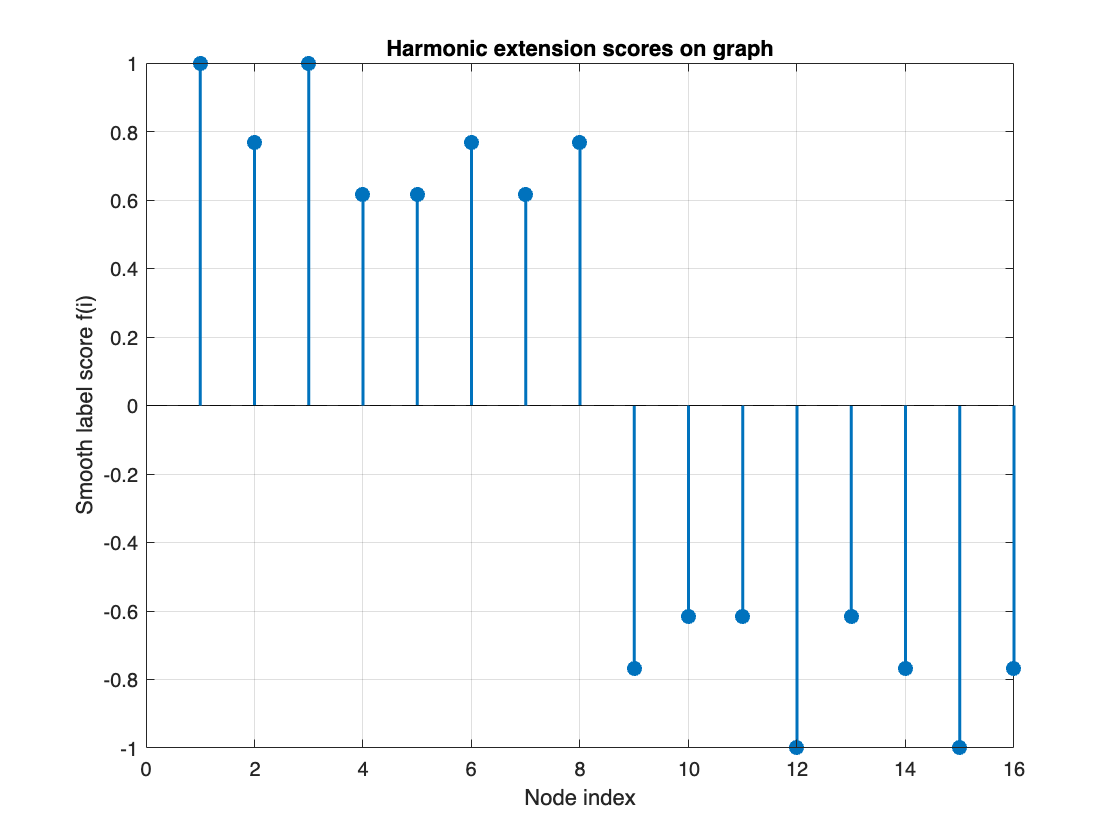

%% ------------------------------------------------------------------------
% STEP 5. Plot the continuous score f(i)
% -------------------------------------------------------------------------
figure('Color','w','Name','Label propagation scores');
stem(1:n, f, 'filled','LineWidth',1.5);
xlabel('Node index'); ylabel('Smooth label score f(i)');
title('Harmonic extension scores on graph');
yline(0,'k--');
grid on;

%% ------------------------------------------------------------------------
% STEP 6. Verify the harmonic property at unlabeled nodes
% -------------------------------------------------------------------------
% For every unlabeled node i, (L f)_i should be ~0.
residual = L*f;

fprintf('Max residual on unlabeled nodes (should be near 0): %.2e\n', ...
        max(abs(residual(Unlabeled))));

Max residual on unlabeled nodes (should be near 0): 1.78e-15


%% ------------------------------------------------------------------------
% STEP 7. Show connection to graph smoothness objective
% -------------------------------------------------------------------------
% The quadratic form f^T L f = sum_{(i,j)} (f_i - f_j)^2 / 2 measures how
% "rough" the labeling is across the graph.
roughness = f' * L * f;
fprintf('Graph smoothness energy f^T L f = %.6f\n', roughness);

Graph smoothness energy f^T L f = 7.384615


%% ------------------------------------------------------------------------
% OPTIONAL EXTENSION: compare with a shortest-path intuition
% -------------------------------------------------------------------------
% If students know graph distance from Chapter 2, ask:
%   Are the unlabeled nodes predicted mostly by whichever labeled set is
%   closer in graph distance?
% This is not exactly what harmonic extension does, but it is close in spirit.
Dsp = distances(G);
for i = Unlabeled
    distToPos = min(Dsp(i, Labeled(yL>0)));
    distToNeg = min(Dsp(i, Labeled(yL<0)));
    fprintf('Node %2d: predicted %+d, nearest + label distance %.1f, nearest - label distance %.1f\n', ...
            i, pred(i), distToPos, distToNeg);
end

Node  2: predicted +1, nearest + label distance 1.0, nearest - label distance 3.0
Node  4: predicted +1, nearest + label distance 1.0, nearest - label distance 2.0
Node  5: predicted +1, nearest + label distance 1.0, nearest - label distance 2.0
Node  6: predicted +1, nearest + label distance 1.0, nearest - label distance 3.0
Node  7: predicted +1, nearest + label distance 1.0, nearest - label distance 2.0
Node  8: predicted +1, nearest + label distance 1.0, nearest - label distance 3.0
Node  9: predicted -1, nearest + label distance 3.0, nearest - label distance 1.0
Node 10: predicted -1, nearest + label distance 2.0, nearest - label distance 1.0
Node 11: predicted -1, nearest + label distance 2.0, nearest - label distance 1.0
Node 13: predicted -1, nearest + label distance 2.0, nearest - label distance 1.0
Node 14: predicted -1, nearest + label distance 3.0, nearest - label distance 1.0
Node 16: predicted -1, nearest + label distance 3.0, nearest - label distance 1.0


%% ------------------------------------------------------------------------
% TEACHING NOTES
% -------------------------------------------------------------------------
% Main ideas to say aloud:
% 1. This is a real learning problem: infer unknown labels from a few known ones.
% 2. The only new assumption is "labels should be smooth on the graph".
% 3. Mathematically, smoothness is measured by f^T L f.
% 4. The solution is just a linear system involving the Laplacian -- nothing
%    beyond Griffin Ch. 5 plus standard linear algebra.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
